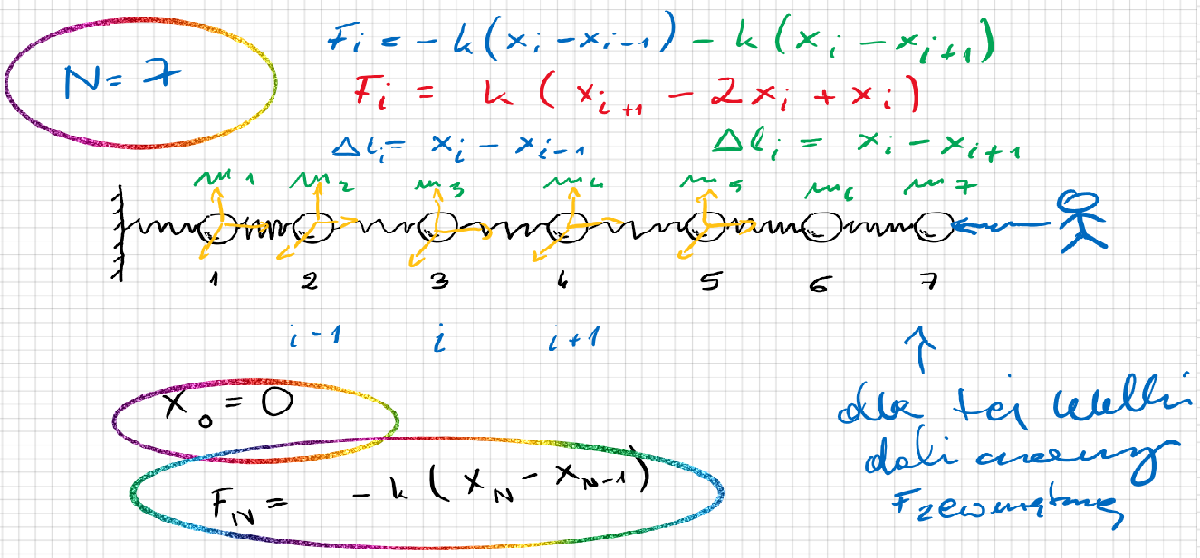

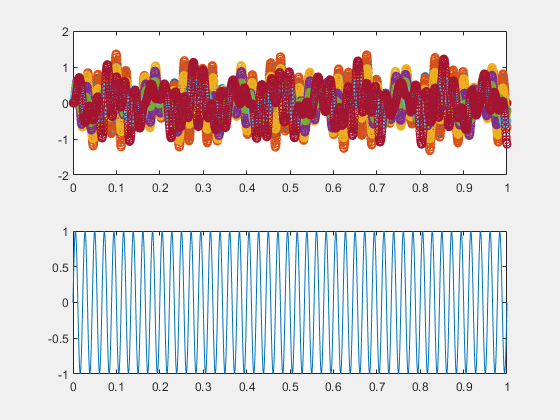

global N k m freq
N = 7; % ilość kulek
k = 1000; % N/m
m = 0.010; % kg

freq = 45; % Hz


t_end = 1;

start = zeros(2*N, 1); % położenia równowagi i zerowe prędkości

figure(1);
clf;
subplot(2,1,1);
ode45(@odefun, [0 t_end], start)

subplot(2,1,2);
t = linspace(0, t_end, 1000);
plot(t, Fexternal(t));

function dqdt = odefun(t, q)
    global N k m
    
    x = q(1:N);         % x(1), x(2), ..., x(N)
    v = q((N+1):(2*N)); % v(1), v(2), ..., v(N)
    
    dxdt = zeros(N, 1);    
    dvdt = zeros(N, 1);
    
    for i = 1: N
        dxdt(i) = v(i);
        dvdt(i) = force(i, x, t) ./ m;
    end
    
    dqdt = zeros(size(q));
    dqdt(1:N) = dxdt;
    dqdt((N+1):(2*N)) = dvdt;
end

function F = Fexternal(t)
    global freq
    A = 1.0;
    phi = 0;
    F = A .* sin(2 * pi * freq .* t + phi);
end

function F = force(i, x, t)    
    global N k m   
    if i == 1
        F = k * (x(i+1) - 2*x(i));
    elseif i == N
        F = -k * (x(N) - x(N-1));
    else
        F = k * (x(i+1) - 2*x(i) + x(i-1)) + Fexternal(t);
    end
end